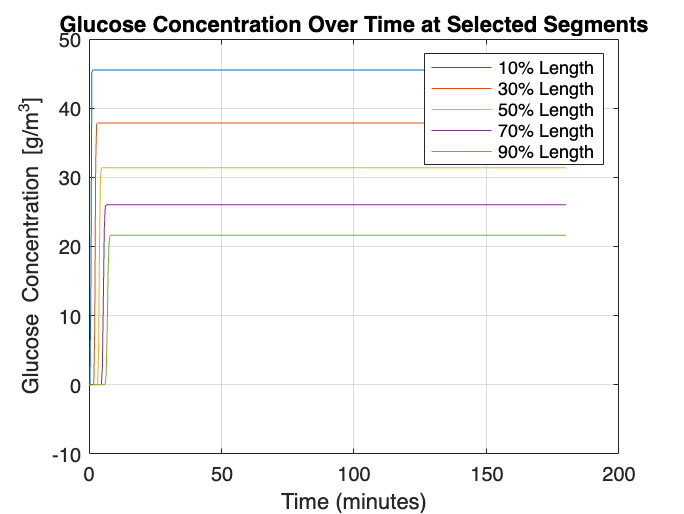

% ==============================
% Glucose Absorption Model using Series CSTR and ODEs
% References embedded inside
% ==============================

clear; clc;

%% ============== PARAMETERS ==============
L_total = 275; % Total length of proximal small intestine [cm] (Guyton & Hall)
dz = 0.6; % Length of each segment [cm] (Research Strategy)
N = round(L_total/dz); % Number of segments (approximately 458)

Q = 1.5; % Flow rate [cm^3/s] (Meyer et al., 1986)
r = 0.9; % Radius of the intestine [cm] (Guyton & Hall)
V = pi * r^2 * dz; % Volume of each segment [cm^3]

k_a = 0.002; % Absorption rate constant [1/s] (D'Argenio et al., 1986)
C_in = 50; % Initial glucose concentration entering the SI [g/m^3] (Hunt and Stubbs, 1975)

Tmax = 10800; % Simulation time [s] = 3 hours (Camilleri et al., 2006)
tspan = linspace(0, Tmax, 500); % Time vector for solver

%% ============== INITIAL CONDITIONS ==============
C0 = zeros(N,1); % All segments start empty (C_i = 0)

%% ============== ODE SYSTEM ==============
ODE = @(t,C) glucoseCSTR(t,C,N,Q,V,k_a,C_in);

%% ============== SOLVE ==============
[t,C] = ode45(ODE, tspan, C0);

%% ============== PLOT 1: Concentration Profiles Over Time ==============
figure;
plot(t/60, C(:,round([N*0.1, N*0.3, N*0.5, N*0.7, N*0.9])));
legend('10% Length','30% Length','50% Length','70% Length','90% Length');
xlabel('Time (minutes)');
ylabel('Glucose Concentration [g/m^3]');
title('Glucose Concentration Over Time at Selected Segments');
grid on;

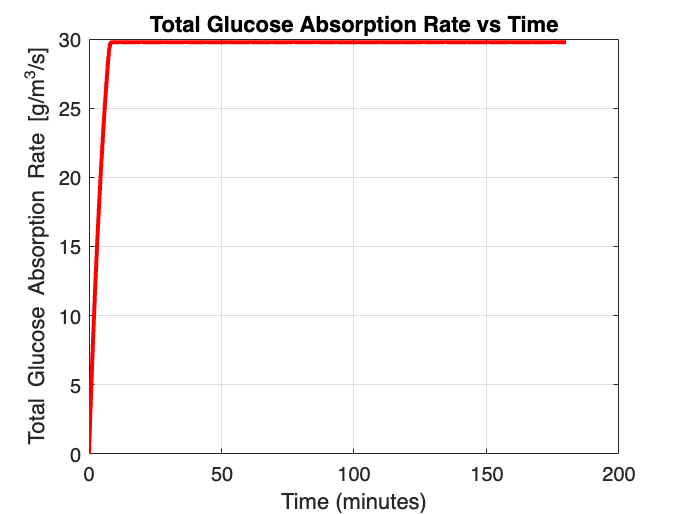


%% ============== PLOT 2: Absorption Rate vs Time ==============
AbsorptionRate = k_a * sum(C,2); % Total absorption rate at each time
figure;
plot(t/60, AbsorptionRate,'r','LineWidth',2);
xlabel('Time (minutes)');
ylabel('Total Glucose Absorption Rate [g/m^3/s]');
title('Total Glucose Absorption Rate vs Time');
grid on;

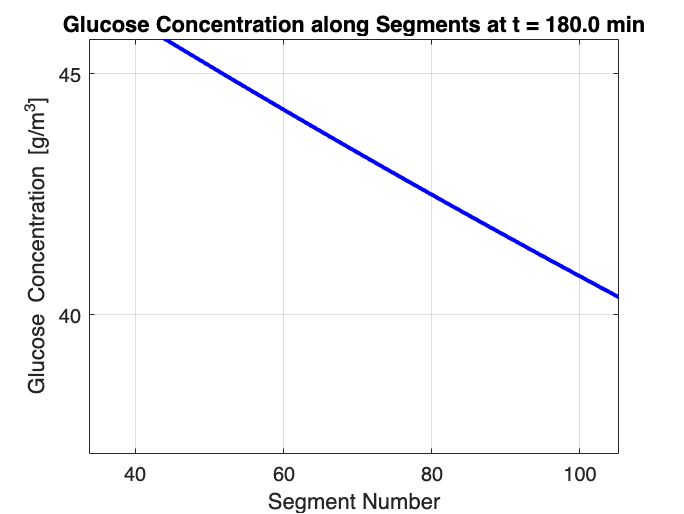


%% ============== PROFESSIONAL ANIMATION ==============
video = VideoWriter('Glucose_Absorption_Animation.avi');
video.FrameRate = 15; % Smooth animation
open(video);

figure;
for i=1:length(t)
    plot(1:N, C(i,:), 'b', 'LineWidth', 2);
    xlabel('Segment Number');
    ylabel('Glucose Concentration [g/m^3]');
    title(['Glucose Concentration along Segments at t = ', num2str(t(i)/60,'%.1f'),' min']);
    axis([1 N 0 C_in+5]);
    grid on;
    frame = getframe(gcf);
    writeVideo(video, frame);
end

close(video);
disp('Animation saved as Glucose_Absorption_Animation.avi');

Animation saved as Glucose_Absorption_Animation.avi



%% ============== ODE FUNCTION ==============
function dCdt = glucoseCSTR(~,C,N,Q,V,k_a,C_in)
    dCdt = zeros(N,1);
    % Segment 1
    dCdt(1) = (Q/V)*(C_in - C(1)) - k_a * C(1);
    % Segments 2 to N
    for i=2:N
        dCdt(i) = (Q/V)*(C(i-1) - C(i)) - k_a * C(i);
    end
end

% ==============
% References:
% - D'Argenio et al., 1986
% - Hunt and Stubbs, 1975
% - Guyton and Hall, Textbook of Medical Physiology
% - Meyer et al., 1986
% - Camilleri et al., 2006
% ==============
